# **Practice 4 **

Name: Zhu Chenhao

HDU ID: 22320630

ITMO ID: 375462

k = 0;

## 1.1 Find all equilibrium points.

%% System 1: Linear System (with k)
syms x1 x2
eq1 = -x1 + k*x1^3 + x2 == 0;
eq2 = -x1 - k*x2 == 0;
sol = solve([eq1, eq2], [x1, x2]);
disp('System 1 Equilibrium Points (with k):');

System 1 Equilibrium Points (with k):


disp([sol.x1, sol.x2]);

$$\left(\begin{array}{cc} 0 & 0 \end{array}\right)$$


%% System 2: Quadratic-Cubic System (with k)  
syms x1 x2
eq1 = k*x1 + x1*x2 == 0;
eq2 = -x2 + x2^2 + x1*x2 - x1^3 == 0;
sol = solve([eq1, eq2], [x1, x2]);
disp('System 2 Equilibrium Points (with k):');

System 2 Equilibrium Points (with k):


disp([sol.x1, sol.x2]);

$$\left(\begin{array}{cc} 0 & 0\\ 0 & 1 \end{array}\right)$$

%% System 3: Modified Van der Pol System (with k)
syms x1 x2
eq1 = k*x2 == 0;
eq2 = -x1 + x2*(1 - x1^2 + 0.1*k*x1^4) == 0;
sol = solve([eq1, eq2], [x1, x2]);
disp('System 3 Equilibrium Points (with k):');

System 3 Equilibrium Points (with k):


disp([sol.x1, sol.x2]);

$$\left(\begin{array}{cc} 0 & 0\\ \frac{\sqrt{5}}{2}-\frac{1}{2} & 1\\ -\frac{\sqrt{5}}{2}-\frac{1}{2} & 1 \end{array}\right)$$

%% System 4: Limit Cycle System (with k)
syms x1 x2
eq1 = k*(x1 - x2)*(1 - x1^2 - x2^2) == 0;
eq2 = (x1 + x2)*(1 - x1^2 - x2^2) == 0;
sol = solve([eq1, eq2], [x1, x2]);
disp('System 4 Equilibrium Points (with k):');

System 4 Equilibrium Points (with k):


disp([sol.x1, sol.x2]);

$$\left(\begin{array}{cc} -1 & 0\\ 0 & 0\\ 1 & 0 \end{array}\right)$$


%% System 5: Cubic Coupled System (with k)
syms x1 x2
eq1 = -x1^3 + k*x2 == 0;
eq2 = k*x1 - x2^3 == 0;
sol = solve([eq1, eq2], [x1, x2]);
disp('System 5 Equilibrium Points (with k):');

System 5 Equilibrium Points (with k):


disp([sol.x1, sol.x2]);

$$\left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

## 1.2 Discuss why these systems are nonlinear.

## 2. Simulation for three different sets of initial conditions:

- first: [0.1 0.1]

- second: [0.5, 0.5]

- third: [1, 1]

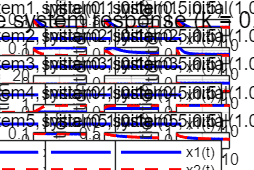

plot_system_responses(0)

## 3. (Optional) Numerically construct a phase portrait of the system.  

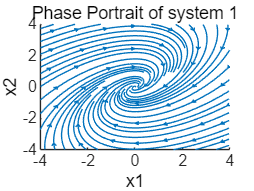

[x,y]=meshgrid(-4:0.2:4,-4:0.2:4); 
f1 = -x+y; 
f2 = -x;
figure;
h=streamslice(x,y,f1,f2); 
title('Phase Portrait of system 1'); 
xlabel('x1','Color',[0 0 0]);ylabel('x2','Color',[0 0 0]); 
xlim([-4,4]);ylim([-4,4]); 

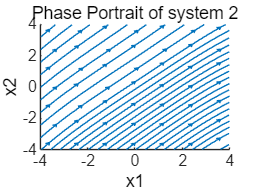

[x,y]=meshgrid(-4:0.2:4,-4:0.2:4); 
f1 = x*y; 
f2 = -y+y.^2+x*y-x.^3;
figure;
h=streamslice(x,y,f1,f2); 
title('Phase Portrait of system 2'); 
xlabel('x1','Color',[0 0 0]);ylabel('x2','Color',[0 0 0]); 
xlim([-4,4]);ylim([-4,4]); 

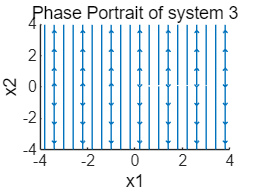

[x,y]=meshgrid(-4:0.2:4,-4:0.2:4); 
f1 = 1e-8*y; 
f2 = -x+y*(1-x^2);
figure;
h=streamslice(x,y,f1,f2); 
title('Phase Portrait of system 3'); 
xlabel('x1','Color',[0 0 0]);ylabel('x2','Color',[0 0 0]); 
xlim([-4,4]);ylim([-4,4]); 

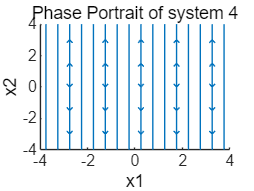

[x,y]=meshgrid(-5:0.1:5,-5:0.1:5); 
f1 = 0.0000001*(x+y)*(1-x^2-y^2); 
f2 = (x+y)*(1-x^2-y^2);
figure;
h=streamslice(x,y,f1,f2); 
title('Phase Portrait of system 4'); 
xlabel('x1','Color',[0 0 0]);ylabel('x2','Color',[0 0 0]); 
xlim([-4,4]);ylim([-4,4]); 

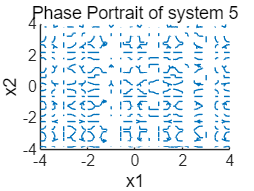

[x,y]=meshgrid(-4:0.1:4,-4:0.1:4); 
f1 = -x^3; 
f2 = -y^3;
figure;
h=streamslice(x,y,f1,f2); 
title('Phase Portrait of system 5'); 
xlabel('x1','Color',[0 0 0]);ylabel('x2','Color',[0 0 0]); 
xlim([-4,4]);ylim([-4,4]); 

## Conclusions

    A ��linear system�� is a system whose mathematical model consists solely of linear expressions. In contrast, a ��nonlinear system�� is a system whose mathematical model includes at least one nonlinear expression.

In the analysis of nonlinear systems, the ��Jacobian matrix�� can be used to linearize the system around equilibrium points. By examining the eigenvalues and eigenvectors of the Jacobian matrix, we can determine the stability and behavior of these equilibrium points.

function plot_system_responses(k)
    
    tspan = [0 10];
    
    initial_conditions = [
        0.1 0.1;
        0.5 0.5;
        1.0 1.0
    ];
    
    figure('Position', [100, 100, 1200, 800]);
    
    for system_num = 1:5
        for ic_idx = 1:3
            subplot_idx = (system_num-1)*3 + ic_idx;
            subplot(5, 3, subplot_idx);
            
            [t, y] = ode45(@(t,y) system_ode(t, y, system_num, k), tspan, initial_conditions(ic_idx,:));
            
            plot(t, y(:,1), 'b-', 'LineWidth', 1.5); hold on;
            plot(t, y(:,2), 'r--', 'LineWidth', 1.5);
            
            title(sprintf('system%d, initial(%.1f,%.1f)', system_num, initial_conditions(ic_idx,1), initial_conditions(ic_idx,2)));
            xlabel('time t');
            ylabel('position');
            legend('x1(t)', 'x2(t)');
            grid on;
            
            y_range = max(max(abs(y))) * 1.1;
            if y_range == 0  
                y_range = 1;
            end
            ylim([-y_range, y_range]);
        end
    end
    
    sgtitle(sprintf('Five system response (k = %.2f)', k));
end


function dydt = system_ode(~, y, system_num, k)
    x1 = y(1); x2 = y(2);
    
    switch system_num
        case 1
            dx1 = -x1 + 2*k*x1^3 + x2;
            dx2 = -x1 - k*x2;
            
        case 2
            dx1 = k*x1 + x1*x2;
            dx2 = -x2 + x2^2 + x1*x2 - x1^3;
            
        case 3
            dx1 = k*x2;
            dx2 = -x1 + x2*(1 - x1^2 - 0.1*k*x1^4);
            
        case 4
            r_squared = x1^2 + x2^2;
            if r_squared >= 1
                dx1 = 0;
                dx2 = 0;
            else
                dx1 = k*(x1 - x2)*(1 - r_squared);
                dx2 = (x1 + x2)*(1 - r_squared);
            end
            
        case 5
            dx1 = -x1^3 + k*x2;
            dx2 = k*x1 - x2^3;
            
        otherwise
            error('Nan');
    end
    
    dydt = [dx1; dx2];
end
